# Doppio pendolo attuato

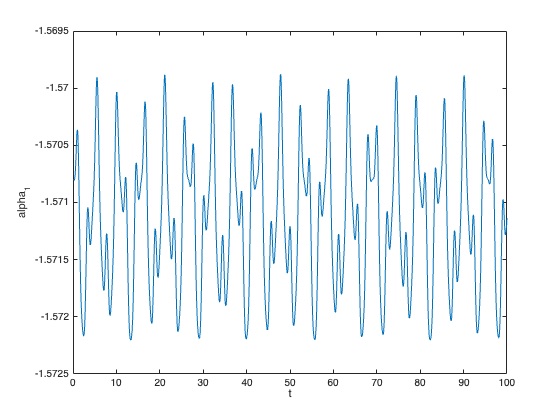

m1 = 20;
m2 = 0.2;
l1 = 7;
l2 = 0.7;
g = 9.81;
tau1 = 0.5;
tau2 = 1;
dt = (0:0.005:100);
%a2 omega2 a1 omega1
x0 =[pi/2,0,-pi/2,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,Y)dp_t_cost(m1,m2,l1,l2,tau1,tau2,Y,t),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,3));
y_m1 = l1.*sin(x(:,3));
x_m2 = l1.*cos(x(:,3))+l2.*cos(x(:,3)+x(:,1));
y_m2 = l1.*sin(x(:,3))+l2.*sin(x(:,3)+x(:,1));

figure;
plot(t,x(:,3));
xlabel("t");
ylabel("alpha_1");

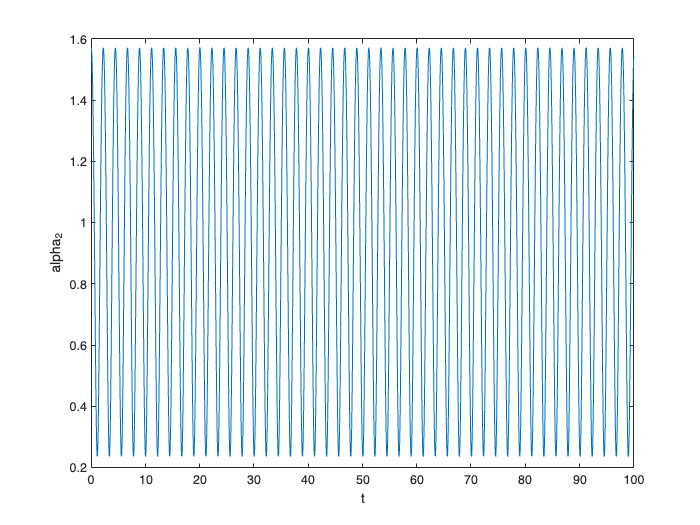

figure;
plot(t,x(:,1));
xlabel("t");
ylabel("alpha_2");

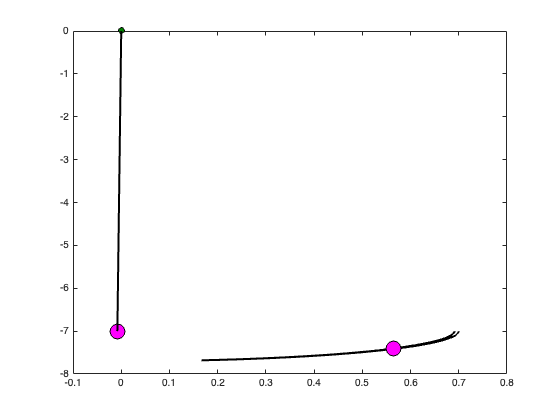



for i = 1:1000
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;
 axis equal;


 hold off;
end

Con condizioni iniziali differenti:

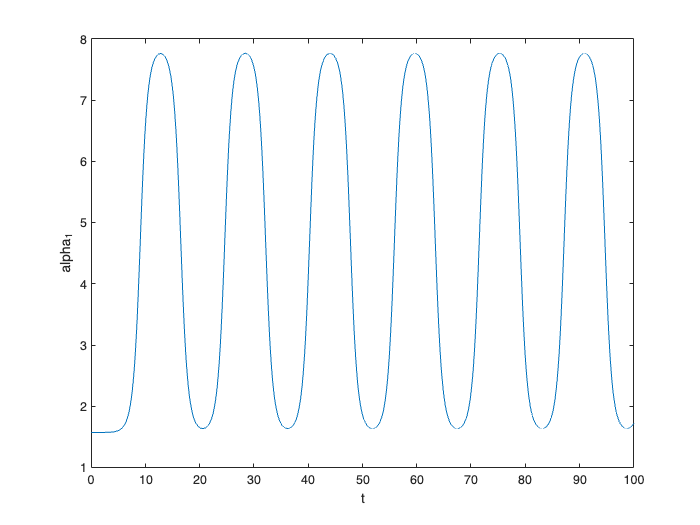

m1 = 20;
m2 = 0.2;
l1 = 7;
l2 = 0.7;
g = 9.81;
tau1 = -1;
tau2 = -0.5;
dt = (0:0.005:100);
%a2 omega2 a1 omega1
x0 =[pi/2,0,pi/2,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,Y)dp_t_cost(m1,m2,l1,l2,tau1,tau2,Y,t),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,3));
y_m1 = l1.*sin(x(:,3));
x_m2 = l1.*cos(x(:,3))+l2.*cos(x(:,3)+x(:,1));
y_m2 = l1.*sin(x(:,3))+l2.*sin(x(:,3)+x(:,1));

figure;
plot(t,x(:,3));
xlabel("t");
ylabel("alpha_1");

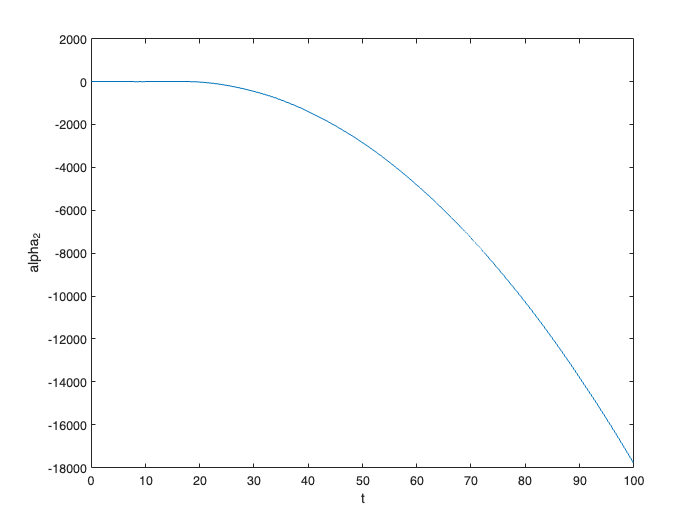

figure;
plot(t,x(:,1));
xlabel("t");
ylabel("alpha_2");

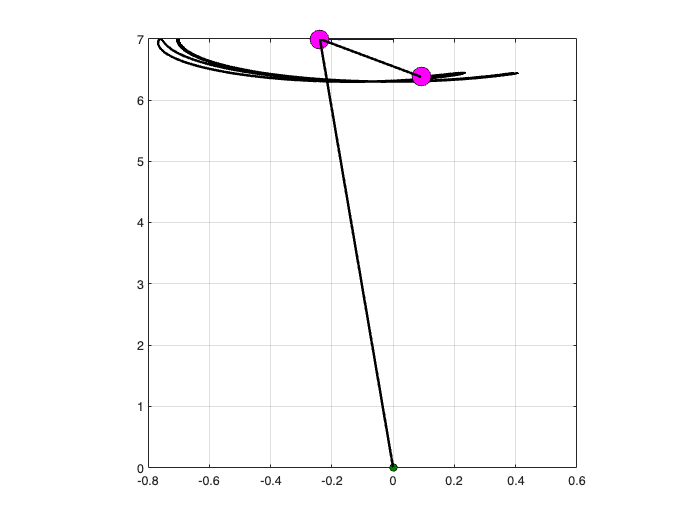



for i = 1:1000
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;  
 axis square;

 hold off;
end

Se inseriamo un PD

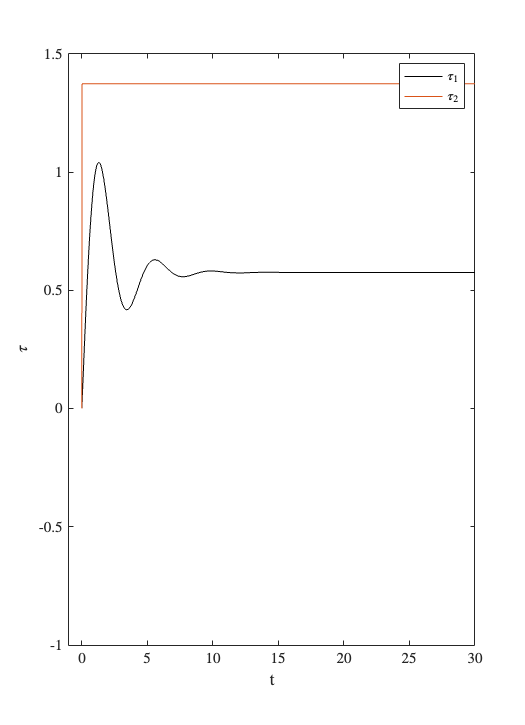

m1 = 20;
m2 = 0.2;
l1 = 7;
l2 = 0.7;
g = 9.81;
kp=1000;
kd=1000;
a1_des = -pi/2;
a2_des= pi/2;
dt = (0:0.005:100);
%a2 omega2 a1 omega1
x0 =[pi/2,0,-pi/2,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,Y)ennesima(m1,m2,l1,l2,kp,kd,a1_des,a2_des,Y,t),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,3));
y_m1 = l1.*sin(x(:,3));
x_m2 = l1.*cos(x(:,3))+l2.*cos(x(:,3)+x(:,1));
y_m2 = l1.*sin(x(:,3))+l2.*sin(x(:,3)+x(:,1));

grafico_momenti_1 = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
plot(t,(kp*(a1_des-x(:,3))-kd*(x(:,4))),'k');
hold on;
plot(t,(kp*(a2_des-x(:,1))-kd*(x(:,2))));
xlabel("t", 'Interpreter','latex');
ylabel("$\tau$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
axis([-1 30 -1 1.5]);
legend('$\tau_1$', '$\tau_2$', 'Interpreter','latex');
hold off
%exportgraphics(grafico_momenti_1,'grafico_momenti.eps','Resolution','300');

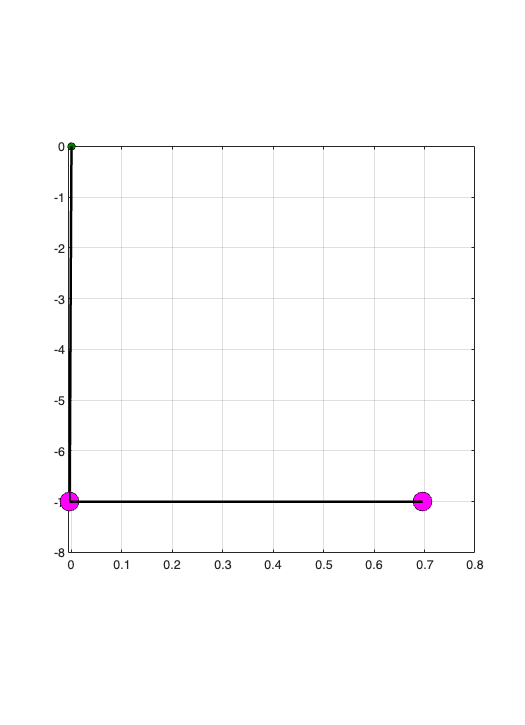

for i = 1:1000
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;  
 axis square;
 hold off;
end

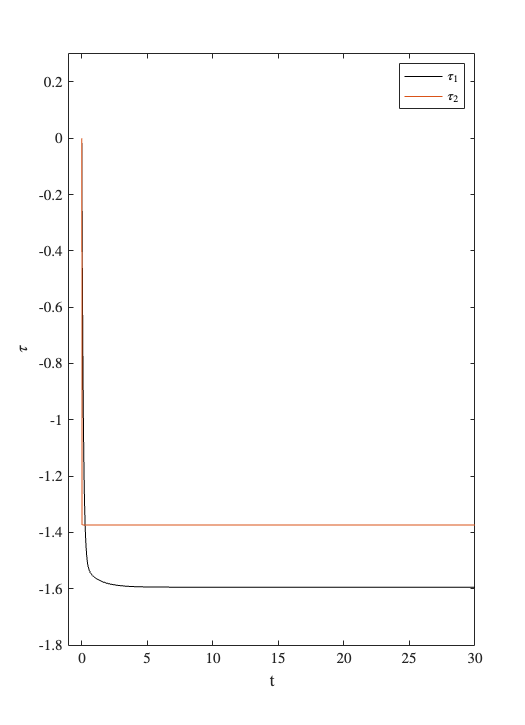

m1 = 20;
m2 = 0.2;
l1 = 7;
l2 = 0.7;
g = 9.81;
kp=10000;
kd=10000;
a1_des = pi/2;
a2_des= pi/2;
dt = (0:0.005:400);
%a2 omega2 a1 omega1
x0 =[pi/2,0,pi/2,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,Y)ennesima(m1,m2,l1,l2,kp,kd,a1_des,a2_des,Y,t),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,3));
y_m1 = l1.*sin(x(:,3));
x_m2 = l1.*cos(x(:,3))+l2.*cos(x(:,3)+x(:,1));
y_m2 = l1.*sin(x(:,3))+l2.*sin(x(:,3)+x(:,1));

grafico_momenti_2 = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
plot(t,(kp*(a1_des-x(:,3))-kd*(x(:,4))),'k');
hold on;
plot(t,(kp*(a2_des-x(:,1))-kd*(x(:,2))));
xlabel("t", 'Interpreter','latex');
ylabel("$\tau$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
axis([-1 30 -1.8 0.3]);
legend('$\tau_1$', '$\tau_2$', 'Interpreter','latex');
hold off
%exportgraphics(grafico_momenti_2,'grafico_momenti_2.eps','Resolution','300');

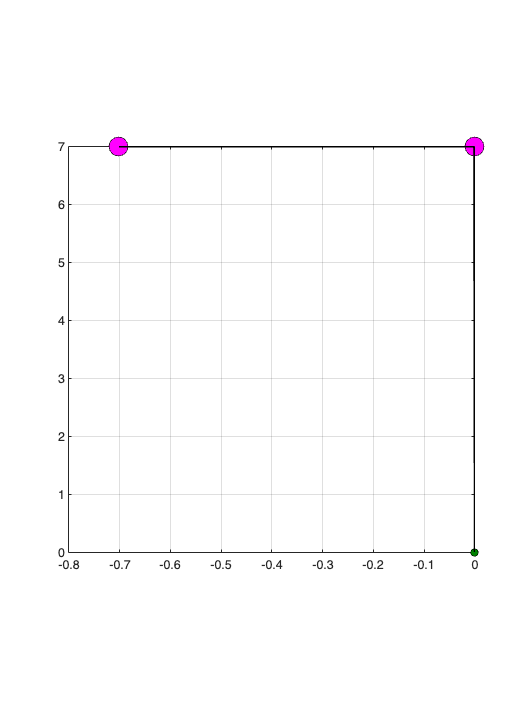

for i = 1:1000
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;  
 axis square;
 hold off;
end

# 2DoF Manipulator

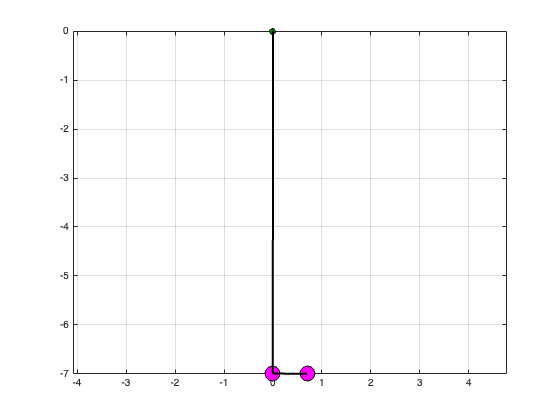

clear;
clearvars;
m1 = 20;
m2 = 0.2;
l1 = 7;
l2 = 0.7;
g = 9.81;
tau1 = 1;
tau2 = 0.5;
dt = (0:0.005:100);
%a2 omega2 a1 omega1
x0 =[pi/2,0,-pi/2,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,Y)manipolatore(t,Y,l1,m1,l2,m2,tau1,tau2),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,3));
y_m1 = l1.*sin(x(:,3));
x_m2 = l1.*cos(x(:,3))+l2.*cos(x(:,3)+x(:,1));
y_m2 = l1.*sin(x(:,3))+l2.*sin(x(:,3)+x(:,1));

for i = 1:1000
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;
 axis equal;


 hold off;
end

Con diverse condizioni iniziali:

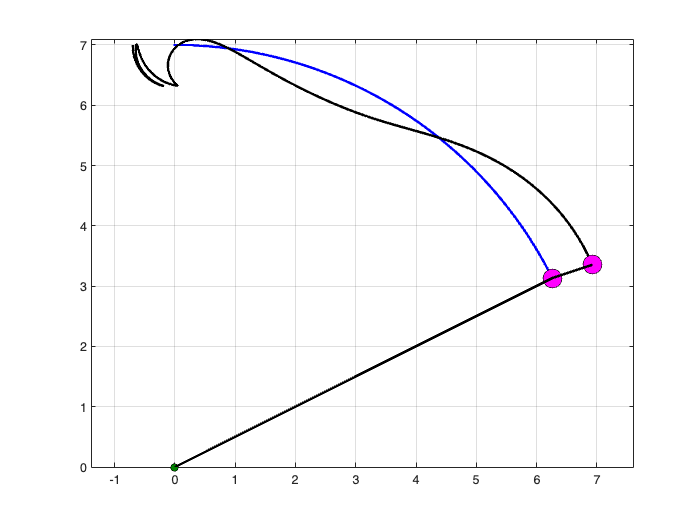

tau1 = 1;
tau2 = -0.5;
x0 =[pi/2,0,pi/2,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,Y)manipolatore(t,Y,l1,m1,l2,m2,tau1,tau2),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,3));
y_m1 = l1.*sin(x(:,3));
x_m2 = l1.*cos(x(:,3))+l2.*cos(x(:,3)+x(:,1));
y_m2 = l1.*sin(x(:,3))+l2.*sin(x(:,3)+x(:,1));

for i = 1:1000
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;
 axis equal;


 hold off;
end

Inserendo un PD

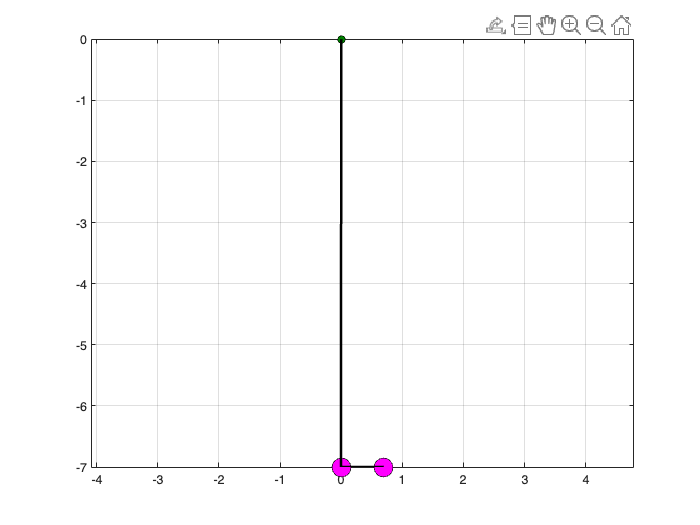

clearvars;
m1 = 20;
m2 = 0.2;
l1 = 7;
l2 = 0.7;
g = 9.81;
kp=1000;
kd=1000;
a1_des = -pi/2;
a2_des= pi/2;
dt = (0:0.005:100);
%a2 omega2 a1 omega1
x0 =[pi/2,0,-pi/2,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,Y)manipolatore_pd(t,Y,l1,m1,l2,m2,a1_des,a2_des,kp,kd),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,3));
y_m1 = l1.*sin(x(:,3));
x_m2 = l1.*cos(x(:,3))+l2.*cos(x(:,3)+x(:,1));
y_m2 = l1.*sin(x(:,3))+l2.*sin(x(:,3)+x(:,1));

for i = 1:1000
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;
 axis equal;


 hold off;
end

Con condizioni iniziali diverse:

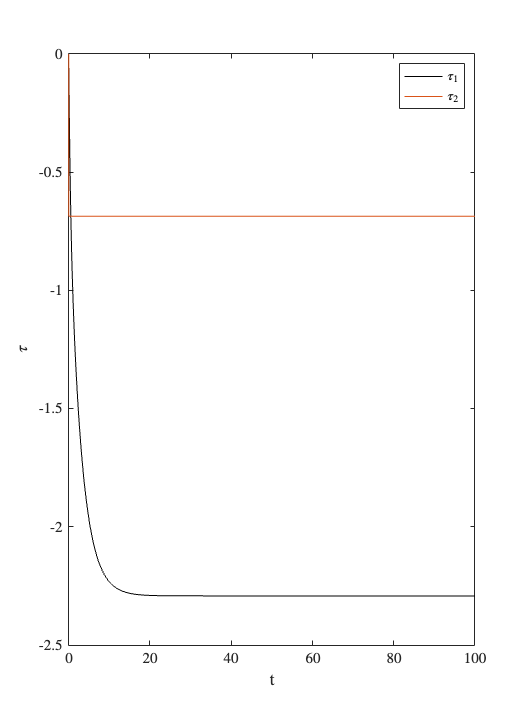

a1_des = pi/2;
a2_des= pi/2;
%a2 omega2 a1 omega1
x0 =[pi/2,0,pi/2,0];
[t,x] = ode45(@(t,Y)manipolatore_pd(t,Y,l1,m1,l2,m2,a1_des,a2_des,kp,kd),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,3));
y_m1 = l1.*sin(x(:,3));
x_m2 = l1.*cos(x(:,3))+l2.*cos(x(:,3)+x(:,1));
y_m2 = l1.*sin(x(:,3))+l2.*sin(x(:,3)+x(:,1));

grafico_momenti_4 = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
plot(t,(kp*(a1_des-x(:,3))-kd*(x(:,4))),'k');
hold on;
plot(t,(kp*(a2_des-x(:,1))-kd*(x(:,2))));
xlabel("t", 'Interpreter','latex');
ylabel("$\tau$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
legend('$\tau_1$', '$\tau_2$', 'Interpreter','latex');
hold off

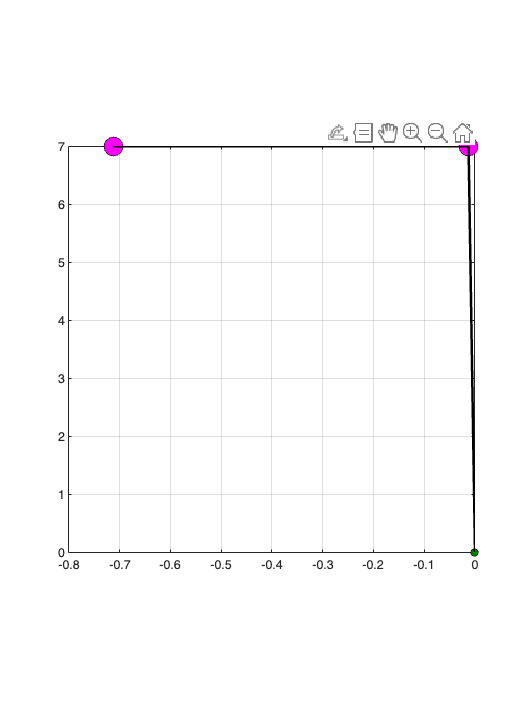

%exportgraphics(grafico_momenti_2,'grafico_momenti_2.eps','Resolution','300');
for i = 1:1000
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;  
 axis square;
 hold off;
end